## Matrix and Data

### [**Hiroyuki Chihara**](https://fiomfd.github.io/)** (University of the Ryukyus, Okinawa Island, Japan)**

1. Data described by matrices

2. Singular value decomposition and low rank approximation

3. Wavelet decomposition with the Haar wavelet and image processing

## **1. Data described by matrices**

### 1-1. Data matrices

Below is a list of height and weight data for 100 people, which can be considered as a $100\times3$ matrix. In general, when the number of individuals is $N$ and each individual has $p$ types of data, the data list can be expressed as a matrix.

load patients
SelfAssessedHealthStatus = categorical(SelfAssessedHealthStatus);
Height=floor(25.4*Height)/10;
Weight=floor(4.53592*Weight)/10;
T = table(Age,Height,Weight,'RowNames',LastName)

T = 100×3 table
                Age    Height    Weight
                ___    ______    ______

    Smith       38     180.3      79.8 
    Johnson     43     175.2      73.9 
    Williams    38     162.5      59.4 
    Jones       40     170.1      60.3 
    Brown       49     162.5      53.9 
    Davis       46     172.7      64.4 
    Miller      33     162.5      64.4 
    Wilson      40     172.7      81.6 
    Moore       28     172.7        83 
    Taylor      31     167.6      59.8 
    Anderson    45     172.7        58 
    Thomas      42     167.6      62.1 
    Jackson     25     180.3      78.9 
    White       39     182.8      91.6 
   

Each individual's data can be plotted as a point on a plane with height  on the horizontal axis and weight on the vertical axis. This is called a scatter plot. By using pseudoinverse or singular value decomposition in linear algebra, it is possible to obtain the best line that shows the  relationship between height and weight using linear regression (the  least squares method).

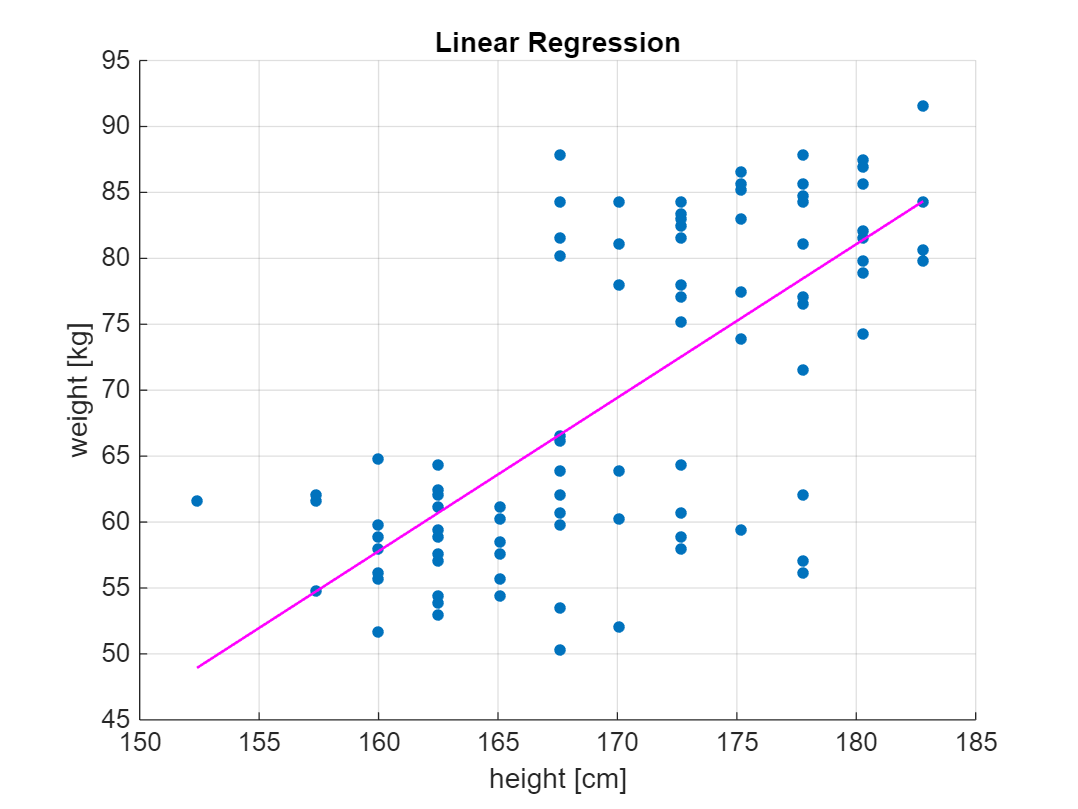

close;
X = [ones(length(Height),1) Height];
b = X\Weight;
yCalc1 = X*b;
scatter(Height,Weight,20,'filled')
hold on
plot(Height,yCalc1,linewidth=1,Color="magenta")
xlabel('height [cm]')
ylabel('weight [kg]')
title('Linear Regression')
grid on

### **1-2. Grayscale image**

A grayscale image is a matrix in which each small square (pixel) has an integer between $0$ and $255$, or a real number between $0$ and $1$ obtained by dividing the integer by $255$. The integer $0$ represents black and the integer $255$ represents white. The number represents the intensity of the color, and the higher the number, the stronger the color. For example, the matrix


$$\pmatrix{0 & 15 & 30 & 45 & 60 & 75
              \cr
              90 & 105 & 120 & 135 & 150 & 165
              \cr
              180 & 195 & 210 & 225 & 240 & 255}$$


becomes the following grayscale image:

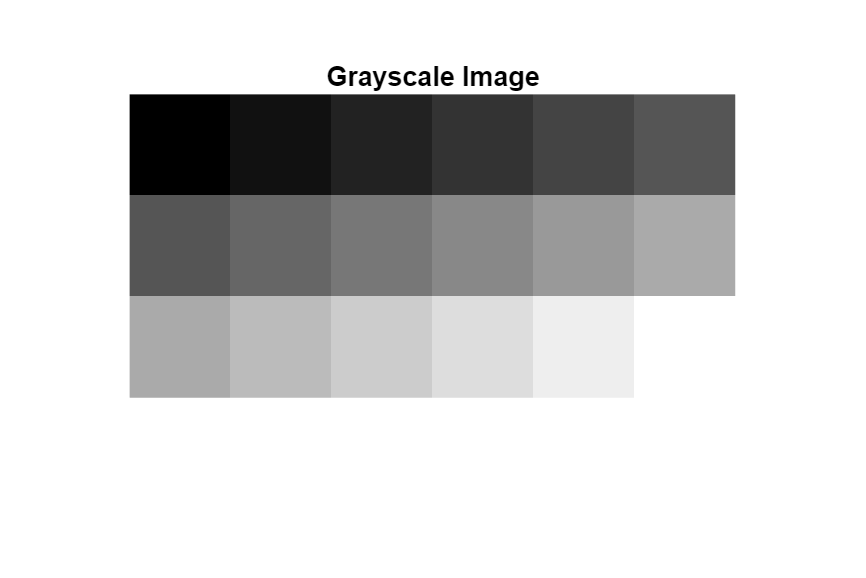

close;
A34=zeros(3,6);
for i=1:3
    for j=1:6
        A34(i,j)=75*(i-1)+15*(j-1);
    end
end

f34=figure;
B34=mat2gray(A34/255);
imshow(B34,'InitialMagnification',10000);
title('Grayscale Image');
set(gcf,'Position',[200,200,450,300]);

%saveas(gcf,'grayscale.png');

### **1-3. RGB image**

An RGB image is created by combining three matrices of grayscale image  data of the same size, each of which is colored with the three primary  colors red, green, and blue. The following shows three $10\times15$ matrices generated by the random numbers created by a programming language, and the RGB image by combining the triplet.

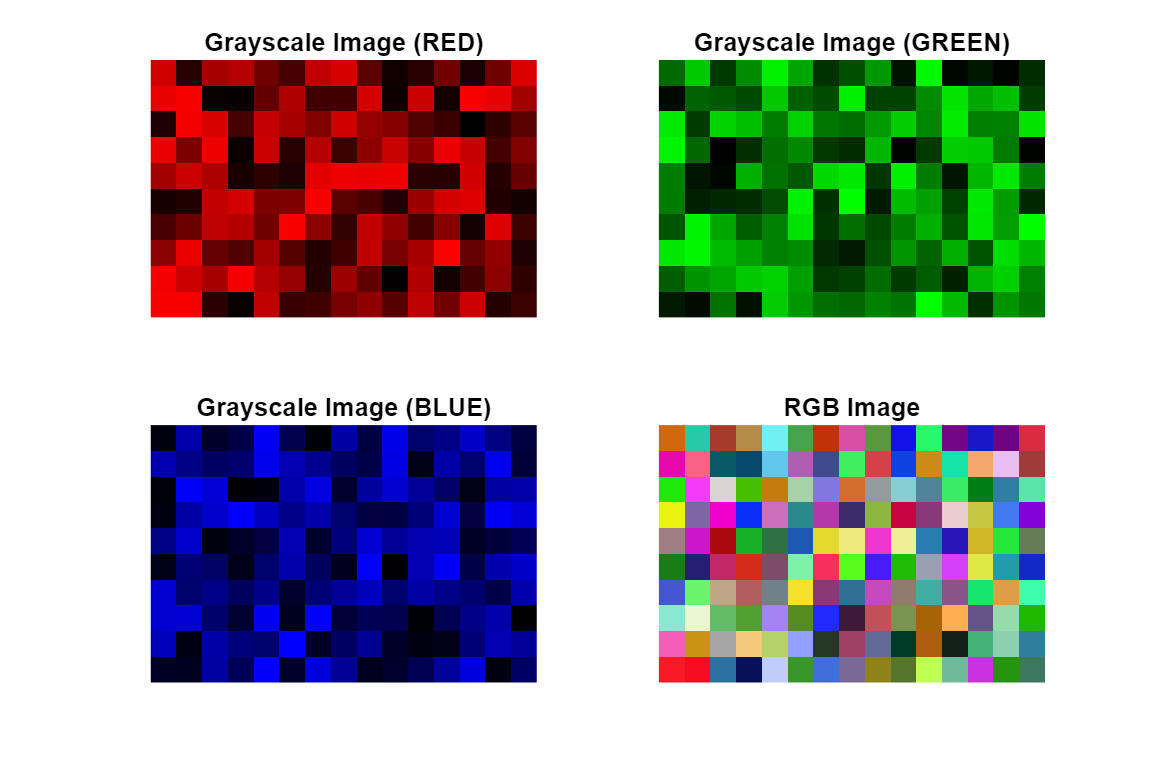

close;
A35=mat2gray(rand(10,15));
B35=mat2gray(rand(10,15));
C35=mat2gray(rand(10,15));
blank35=mat2gray(zeros(10,15));
X35(:,:,1)=A35;
X35(:,:,2)=blank35;
X35(:,:,3)=blank35;
Y35(:,:,1)=blank35;
Y35(:,:,2)=B35;
Y35(:,:,3)=blank35;
Z35(:,:,1)=blank35;
Z35(:,:,2)=blank35;
Z35(:,:,3)=C35;
RGB35(:,:,1)=A35;
RGB35(:,:,2)=B35;
RGB35(:,:,3)=C35;

f35=figure;
subplot(2,2,1)
imshow(X35,'InitialMagnification',1000);
title('Grayscale Image (RED)');
subplot(2,2,2)
imshow(Y35,'InitialMagnification',1000);
title('Grayscale Image (GREEN)');
subplot(2,2,3)
imshow(Z35,'InitialMagnification',1000);
title('Grayscale Image (BLUE)');
subplot(2,2,4)
imshow(RGB35,'InitialMagnification',1000);
title('RGB Image');
set(gcf,'Position',[200,200,600,400]);

### 1-4. Grayscale movies

If multiple grayscale images are displayed in succession, we have a  grayscale movie. Here, we will generate 60 randomly generated matrices  of and animate them.

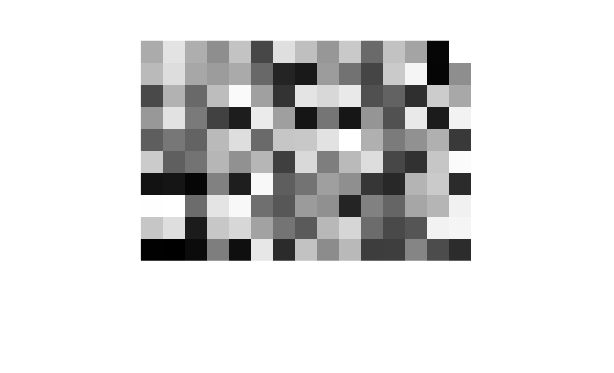

close;
for k=1:60
    Y36=mat2gray(rand(10,15));
    imshow(Y36,'InitialMagnification',2000);
    drawnow nocallbacks
    pause(0.5)
end

### 1-5. RGB movie

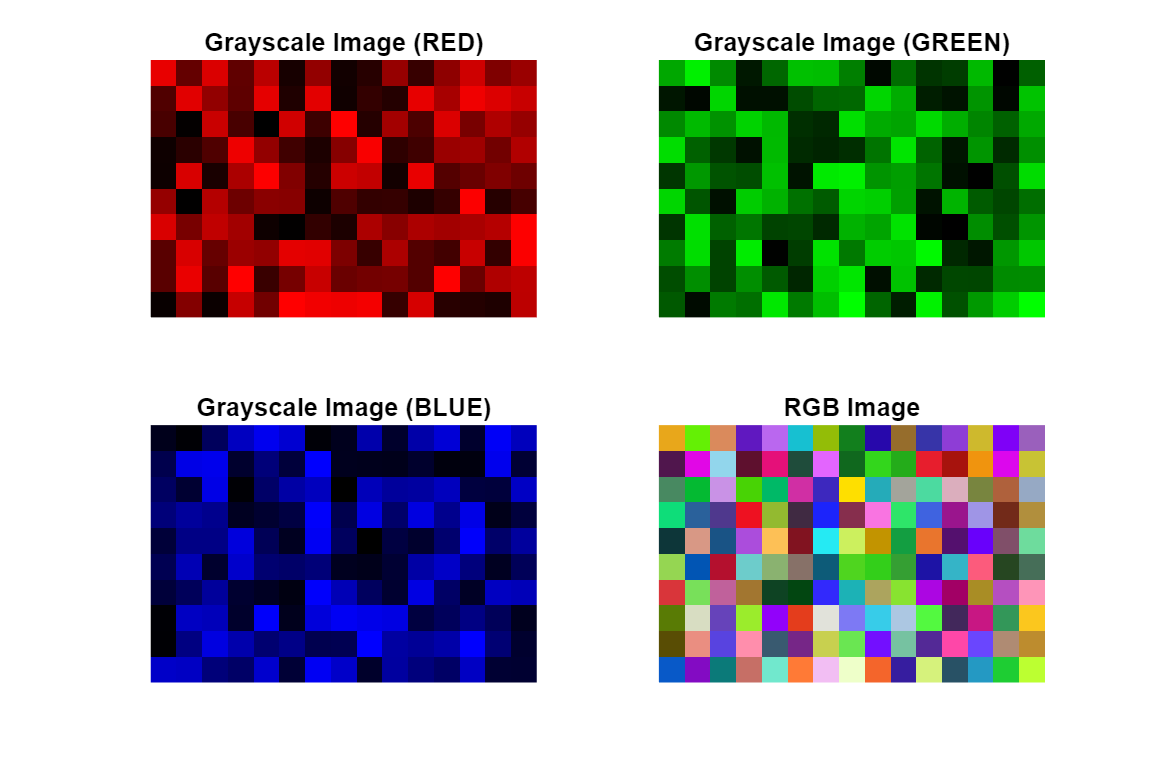

close;
for k=1:60
    A37=mat2gray(rand(10,15));
    B37=mat2gray(rand(10,15));
    C37=mat2gray(rand(10,15));
    blank37=mat2gray(zeros(10,15));
    X37(:,:,1)=A37;
    X37(:,:,2)=blank37;
    X37(:,:,3)=blank37;
    Y37(:,:,1)=blank37;
    Y37(:,:,2)=B37;
    Y37(:,:,3)=blank37;
    Z37(:,:,1)=blank37;
    Z37(:,:,2)=blank37;
    Z37(:,:,3)=C37;
    RGB37(:,:,1)=A37;
    RGB37(:,:,2)=B37;
    RGB37(:,:,3)=C37;
    subplot(2,2,1)
    imshow(X37,'InitialMagnification',1000);
    title('Grayscale Image (RED)');
    subplot(2,2,2)
    imshow(Y37,'InitialMagnification',1000);
    title('Grayscale Image (GREEN)');
    subplot(2,2,3)
    imshow(Z37,'InitialMagnification',1000);
    title('Grayscale Image (BLUE)');
    subplot(2,2,4)
    imshow(RGB37,'InitialMagnification',1000);
    title('RGB Image');
    set(gcf,'Position',[200,200,600,400]);
    drawnow nocallbacks
    pause(0.5)
end

## 2. Singular Value Decomposition

Let $$\mathbb{K}$$ denote $\mathbb{R}$ or $\mathbb{C}$, and let $A\in\mathbb{K}^{m{\times}n}$. Set $r=\text{rank}(A)$ for short. 

We state well-known facts. Set  $r=\text{rank}(A)$ for short. We state well-known facts.  

- 
$$\text{rank}({A^\ast}A) = \text{rank}(AA^\ast) = \text{rank}(A), \quad  {A^\ast}A \geq 0.$$


- There exist positive numbers $\sigma_1\geq\dots\geq\sigma_r>0$ such that $\det(zE_n-A) = z^{n-r}(z-\sigma_1)\cdots(z-\sigma_r).$

- There exist an orthonormal system $\{u_1,\dots,u_m\}$ of $\mathbb{K}^m$and an orthonormal system$\{v_1,\dots,v_n\}$  of $\mathbb{K}^n$ such that 


$$A=U{\Sigma}V^\ast=\sum_{l=1}^r\sigma_lu_lv_l^\ast, \quad U=[u_1,\dots,u_m], \quad V=[v_1,\dots,v_n], \quad \Sigma=\pmatrix{\sigma_1 &  & & \cr & \ddots & & \cr & & \sigma_r & \cr & & &}.$$


### 2-1. Best low rank approximation

Let $A\in\mathbb{K}^{m{\times}n}$. Set $r=\text{rank}(A)$ for short. Suppose that the SVD of $A$ is given by 


$$A=U{\Sigma}V^\ast=\sum_{l=1}^r\sigma_lu_lv_l^\ast.$$


Set 


$$A_k=U{\Sigma}V^\ast=\sum_{l=1}^k\sigma_lu_lv_l^\ast, \quad k=1,\ldots,r.$$


Then $\text{rank}(A_k)=k$. It is well-known that $A_k$ is the best approximation of $A$ among $m{\times}n$ matrices with rank $k$. 

More precisely we have the Eckart-Young inequality of the form

$||A-B|| \geq ||A-A_k||, 
\quad
B\in\mathbb{K}^{m{\times}n}, 
\quad
\text{rank}(B)=k$,

where  $||\cdot||$ is the spectral norm of matrices defined by 


$$||B||:=
\max_{x \in \mathbb{K}^n\setminus\{0\}}
\frac{|Bx|}{|x|},$$


and $|\cdot|$ is the standard norm of numeric vectors. 

The same inequlity holds if we replace the spectral norm by the Frobenius norm or the nuclear norm. 

clear;
% l. oad image file
RGB=imread('CityU.jpg');
[s1,s2,s3]=size(RGB);
R2=max(s1,s2);
RGB=imresize(RGB, 512/R2);
[R,G,B] = imsplit(RGB);
% imshow(RGB)
% whos R, whos G, whos B

DR=double(R);
DG=double(G);
DB=double(B);

for r=1:100
    [UR,SR,VR]=svds(DR,r);
    DRr=UR*SR*VR';
    Rr=uint8(DRr);
    [UG,SG,VG]=svds(DG,r);
    DGr=UG*SG*VG';
    Gr=uint8(DGr);
    [UB,SB,VB]=svds(DB,r);
    DBr=UB*SB*VB';
    Br=uint8(DBr);
    SVD(:,:,1,r)=(Rr);
    SVD(:,:,2,r)=(Gr);
    SVD(:,:,3,r)=(Br);
end

k =20;
subplot(1,2,1);
imshow(RGB);
title('Original');
subplot(1,2,2);
imshow(SVD(:,:,:,k));
title('Low Rank Approximation');
set(gcf,'Position',[600,200,1000,400]);

## **3. Wavelet decomposition and image processing**

### 3-1. The Haar wavelet

The discrete wavelet is a pair of orthonomal two vectors $\vec{u}$ and $\vec{v}$ satisfying some condition, and the most typical example of the discrete wavelets is the Haar wavelet. They are very simple vectors: 


$$\vec{u}
=
\frac{1}{\sqrt{2}}
\pmatrix{1 \cr 1 \cr 0 \cr \vdots \cr 0},
\quad
\vec{v}
=
\frac{1}{\sqrt{2}}
\pmatrix{1 \cr -1 \cr 0 \cr \vdots \cr 0}.$$


Roughly speaking the discrete wavelet transform by the Haar wavelet is to take averages of neighboring elements. The elements of a vector are transformed  to the average of neighboring two elements, and the elements of a matrix are converted to the average of neighboring 2 by 2 elements. The following examples show the outcomes of repeating the discere wavelet tranform twice: 


$$\vec{a}_0=\pmatrix{1 \cr 3 \cr 5 \cr 7}
\mapsto 
\vec{a}_1=\pmatrix{2 \cr 2 \cr 6 \cr 6}
\mapsto
\vec{a}_2=\pmatrix{4 \cr 4 \cr 4 \cr 4}$$



$$A_0
=
\pmatrix{0 & 2 & 4 & 6 
              \cr
              8 & 10 & 12 & 14
              \cr
              16 & 18 & 20 & 22
              \cr
              24 & 26 & 28 & 30}
\mapsto 
A_1
=
\pmatrix{5 & 5 & 9 & 9
              \cr
              5 & 5 & 9 & 9 
              \cr
              21 & 21 & 25 & 25 
              \cr
              21 & 21 & 25 & 25 }
\mapsto 
A_2
=
\pmatrix{15 & 15 & 15 & 15
              \cr
              15 & 15 & 15 & 15
              \cr
              15 & 15 & 15 & 15
              \cr
              15 & 15 & 15 & 15}$$


The output such as $\vec{a}_\ell$ and $A_\ell$ of $\ell$ times operations is said to be the approximation part of level $\ell$, and the remainder term such as $\vec{a}_0 - \vec{a}_\ell$ and $A_0 - A_\ell$ is called the detail part of level $\ell$. 

We shall observe the wavelet decomposition of image data using the Haar wavelet.

clear;
RGB=imread('CityU.jpg');
[s1,s2,s3]=size(RGB);
R2=max(s1,s2);
RGB=imresize(RGB, 512/R2);
[R,G,B] = imsplit(RGB);
l =4
if l==0
   RGBA=RGB;
   RGBZ=zeros(s1,s2,s3);
   else
   [RC,RS]=wavedec2(R,7,'haar');
   [GC,GS]=wavedec2(G,7,'haar');
   [BC,BS]=wavedec2(B,7,'haar');
   RAA=appcoef2(RC,RS,'haar',l);
   GAA=appcoef2(GC,GS,'haar',l);
   BAA=appcoef2(BC,BS,'haar',l);
   RA=mat2gray(RAA);
   GA=mat2gray(GAA);
   BA=mat2gray(BAA);
   [RHH,RVV,RDD] = detcoef2('all',RC,RS,l);
   [GHH,GVV,GDD] = detcoef2('all',GC,GS,l);
   [BHH,BVV,BDD] = detcoef2('all',BC,BS,l);
   RZZ=RHH+RVV+RDD;
   RZ=mat2gray(RZZ);
   GZZ=GHH+GVV+GDD;
   GZ=mat2gray(GZZ);
   BZZ=BHH+BVV+BDD;
   BZ=mat2gray(BZZ);
   RGBA(:,:,1)=RA;
   RGBA(:,:,2)=GA;
   RGBA(:,:,3)=BA;
   RGBZ(:,:,1)=RZ;
   RGBZ(:,:,2)=GZ;
   RGBZ(:,:,3)=BZ;
end

figure;
subplot(1,3,1);
imshow(RGB);
title('Original RGB Image');
subplot(1,3,2);
imshow(RGBA);
title('Approximation');
subplot(1,3,3);
imshow(RGBZ);
title('Detail');
set(gcf,'Position',[600,200,1200,400]);